# MRS onto ISCs calcium

% room temp, 6K+ ACSF, dissected at p5-p6, 16-24 hours in vitro
% tecta-cre;Cx26fl/fl;R26-GCamP3fl/+
% MRS washed on at ~ 7 min, with some variability between movies
defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\Calcium Imaging\6K room and phys\ISC MRS2500'

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\Calcium Imaging\6K room and phys\ISC MRS2500'

cd(defaultDir);


% This analysis was whole field ROI over all ISCs 

tectacx1 = load('ISCcalciumMRS1.mat');
tectacx2 = load('ISCcalciumMRS2.mat');
tectacx3 = load('ISCcalciumMRS3.mat');
tectacx4 = load('ISCcalciumMRS4.mat');
tectacx5 = load('ISCcalciumMRS5.mat');

% calcium event frequency

preF = [tectacx1.meanFreqPre,tectacx2.meanFreqPre,tectacx3.meanFreqPre,tectacx4.meanFreqPre,tectacx5.meanFreqPre];
postF = [tectacx1.meanFreqPost,tectacx2.meanFreqPost,tectacx3.meanFreqPost,tectacx4.meanFreqPost,tectacx5.meanFreqPost];

conditions = {'Baseline','+ MRS2500'};
ylbl1 = 'Calcium events per minute';
dim = [1.5 3];
compare2(preF,postF,conditions,ylbl1,dim);

   2.0626e-04



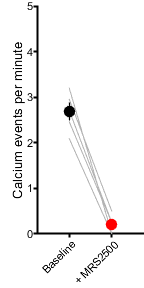

ylim([0 5]);

% Example trace

examp1 = load('raw frameIntensity ISCMRS3.mat');

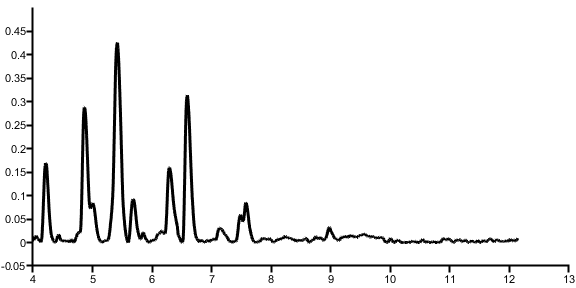


ROIF = smooth(examp1.ROIF); % smoothing function applied to each ROI 
ROIF = ROIF';
    baseline = median(ROIF(:)); % this probably isn't the best
        % drifting baseline not affected by bleach correct 
        % maybe take a local minimum as baseline? 
    
    for x = 1:length(ROIF)
        if x < 26
            baseline(x) = min(ROIF(x:x+25));
        elseif x > 1224
            baseline(x) = min(ROIF(x-25:x));
        else
            baseline(x) = min(ROIF(x-25:x+25));
        end
        ROIdF(x) = (ROIF(x)-baseline(x))/baseline(x);
    end
figure

plot(examp1.time/60,ROIdF,'k','LineWidth', 2)
ylim([-0.05 0.5]);
xlim([4 13])
figQuality(gcf,gca,[6 3])

examp2 = load('raw frameIntensity ISCMRS2.mat');

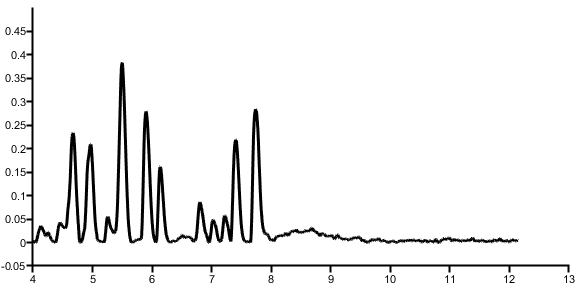


ROIF = smooth(examp2.ROIF); % smoothing function applied to each ROI 
ROIF = ROIF';
    baseline = median(ROIF(:)); % this probably isn't the best
        % drifting baseline not affected by bleach correct 
        % maybe take a local minimum as baseline? 
    
    for x = 1:length(ROIF)
        if x < 26
            baseline(x) = min(ROIF(x:x+25));
        elseif x > 1224
            baseline(x) = min(ROIF(x-25:x));
        else
            baseline(x) = min(ROIF(x-25:x+25));
        end
        ROIdF(x) = (ROIF(x)-baseline(x))/baseline(x);
    end
figure

plot(examp2.time/60,ROIdF,'k','LineWidth', 2)
ylim([-0.05 0.5]);
xlim([4 13])
figQuality(gcf,gca,[6 3])

% Grid analysis - V3
% new analysis to replicate 1x analysis of baseline 

% - event freq (# of waves/min)

scale = 0.83027; %um/pixel
areaPG = (10*scale)^2 % area per grd

areaPG = 68.9348

preTime = 8.09;
postTime = 4.04;
maxTime = preTime + postTime;

%MRS2500 on at 1000 frames
con1 = load('20190911 exp281 mouse 1 tecta cx26flfl gcamp3 prep 2 movie 1 mrs2500_ISCdata.mat')

con1 = struct with fields:
    ISCstruct: [1×1 struct]


con1Pre = 0;
con1Post = 0;
for i = 1:length(con1.ISCstruct.event)
    if con1.ISCstruct.event(i).timeStart < 1000
        con1Pre = con1Pre+1;
    else
        con1Post = con1Post+1;
    end
end

con1FreqPre = (con1Pre/preTime)/(size(con1.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2
con1FreqPost = (con1Post/postTime)/(size(con1.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2

con2 = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 1 movie 3 2x mrs2500_ISCdata.mat')

con2 = struct with fields:
    ISCstruct: [1×1 struct]


con2Pre = 0;
con2Post = 0;
for i = 1:length(con2.ISCstruct.event)
    if con2.ISCstruct.event(i).timeStart < 1000
        con2Pre = con2Pre+1;
    else
        con2Post = con2Post+1;
    end
end

con2FreqPre = (con2Pre/preTime)/(size(con2.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2
con2FreqPost = (con2Post/postTime)/(size(con2.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2

con3 = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 2 movie 3 2x mrs2500_ISCdata.mat')

con3 = struct with fields:
    ISCstruct: [1×1 struct]


con3Pre = 0;
con3Post = 0;
for i = 1:length(con3.ISCstruct.event)
    if con3.ISCstruct.event(i).timeStart < 1000
        con3Pre = con3Pre+1;
    else
        con3Post = con3Post+1;
    end
end

con3FreqPre = (con3Pre/preTime)/(size(con3.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2
con3FreqPost = (con3Post/postTime)/(size(con3.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2

con4 = load('20190911 exp281 mouse 1 tecta cx26flfl gcamp3 prep 1 movie 1 mrs2500_ISCdata.mat')

con4 = struct with fields:
    ISCstruct: [1×1 struct]


con4Pre = 0;
con4Post = 0;
for i = 1:length(con4.ISCstruct.event)
    if con4.ISCstruct.event(i).timeStart < 1000
        con4Pre = con4Pre+1;
    else
        con4Post = con4Post+1;
    end
end

con4FreqPre = (con4Pre/preTime)/(size(con4.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2
con4FreqPost = (con4Post/postTime)/(size(con4.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2

con5 = load('20190918 exp282 tecta cx26 flfl gcamp mouse 9 prep 1 movie 3 2x mrs2500-1_ISCdata.mat')

con5 = struct with fields:
    ISCstruct: [1×1 struct]


con5Pre = 0;
con5Post = 0;
for i = 1:length(con5.ISCstruct.event)
    if con5.ISCstruct.event(i).timeStart < 1000
        con5Pre = con5Pre+1;
    else
        con5Post = con5Post+1;
    end
end

con5FreqPre = (con5Pre/preTime)/(size(con5.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2
con5FreqPost = (con5Post/postTime)/(size(con5.ISCstruct.rois,2)*areaPG)*10000; %per 0.01 mm2



conFreqPre = [con1FreqPre,con2FreqPre,con3FreqPre,con4FreqPre,con5FreqPre]

conFreqPre =     5.8879    3.4008    4.5382    4.3470    4.9277


conFreqPost = [con1FreqPost,con2FreqPost,con3FreqPost,con4FreqPost,con5FreqPost]

conFreqPost =     1.0719    0.6191         0         0    0.5482




conditions = {'Baseline','+ MRS2500'};
ylbl1 = 'Events per minute';
dim = [1 2];
[fig1 h p] = compare2_2(conFreqPre,conFreqPost,conditions,ylbl1,dim);

   3.0798e-04



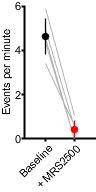

ylim([0 6]);
yticks([0 2 4 6]);

subP = handleTheSubplot({fig1,fig1},[1 2]);

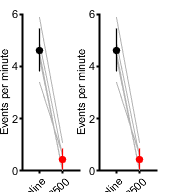

figQuality(subP,gca,[1.8 2])

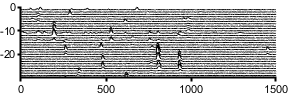


% show ROI raster from control and cKO 
n = length(con1.ISCstruct.corrROIs);
t = 1500;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con1.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

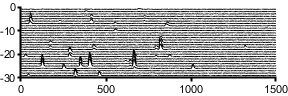


n = length(con2.ISCstruct.corrROIs);
t = 1500;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con2.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

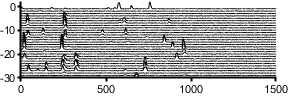


n = length(con3.ISCstruct.corrROIs);
t = 1500;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con3.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

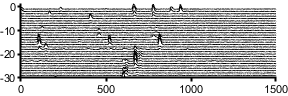


n = length(con4.ISCstruct.corrROIs);
t = 1500;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con4.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

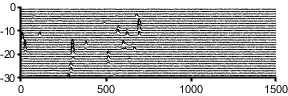


n = length(con5.ISCstruct.corrROIs);
t = 1500;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con5.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])